clear all;
close all;

% Gaussian Process example
meanfunc = [];                             % empty: don't use a mean function
covfunc = {@covSum,{@covLIN,@covConst}};   % Linear covariance function
likfunc = @likGauss;                       % Gaussian likelihood
hyp = struct('mean', [],'cov', 0, 'lik', -1);

sigma = 0.01;   % Added sigma which will be adjusted
N = 50;        % Change N from 50 to 100
x = rand(N,1);
[Y,y,f] = data(N, 3, sigma);

hyp2 = minimize(hyp, @gp, -100, @infGaussLik, meanfunc, covfunc, likfunc, Y, y);    % Change x to Y

Function evaluation      0;  Value 5.917046e-01
Function evaluation     17;  Value -1.052756e+02
Function evaluation     20;  Value -1.100502e+02
Function evaluation     25;  Value -1.100502e+02
Function evaluation     31;  Value -1.100548e+02
Function evaluation     33;  Value -1.100575e+02
Function evaluation     35;  Value -1.100578e+02
Function evaluation     38;  Value -1.100578e+02
Function evaluation     40;  Value -1.100578e+02
Function evaluation     43;  Value -1.100578e+02
Function evaluation     46;  Value -1.100578e+02
Function evaluation     48;  Value -1.100578e+02
Function evaluation     58;  Value -1.100578e+02



% xs = (0:0.1:1)';
[a,b,c] = data(N, 3, sigma);  % Remove xs, replace with [a,b,c]
[mu s2] = gp(hyp2, @infGaussLik, meanfunc, covfunc, likfunc, Y, y, a); % Change x to Y & xs to a

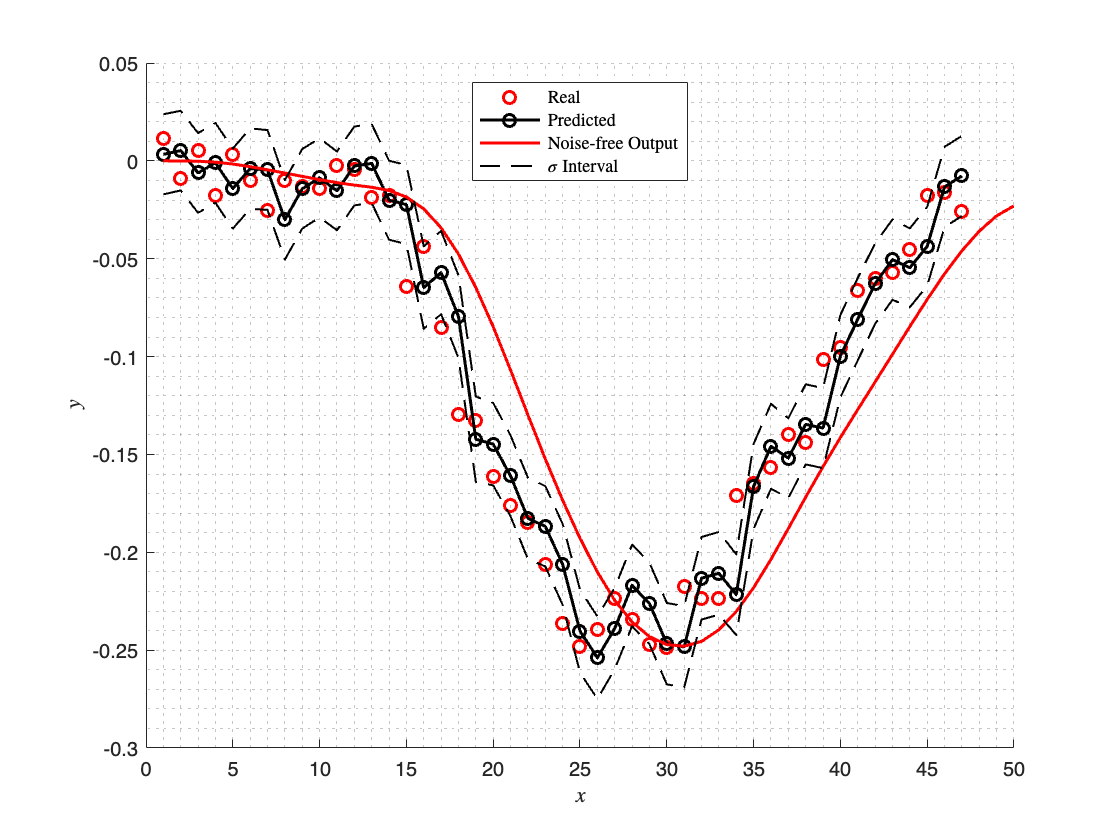

figure(1);hold on

p1 = plot(b,'ro','LineWidth',1.5);
p2 = plot(mu,'ko-','Linewidth',1.5);
p3 = plot(c,'r','Linewidth',1.5);
p4 = plot([1:length(mu)],mu-sqrt(s2),'k--','Linewidth',1);
     plot([1:length(mu)],mu+sqrt(s2),'k--','Linewidth',1);

leg1 = legend([p1,p2, p3, p4],{'Real','Predicted','Noise-free Output','$\sigma$ Interval'},'Interpreter','latex','Location','best');
grid minor
xlabel('$x$','Interpreter','latex')
ylabel('$y$','Interpreter','latex')

function [Y,y,f] = data(N,m,sigma) 
    % N: number of generated samples
    % m: predictor input length (dimension of the input)
    % sigma: noise standard deviation
    m = m+1;
    randn('seed',100);  % Added from Learn
    x = randn(N,1);
    [b,a] = butter(4,0.05);
    f = filter(b,a,x);
    temp = f + sigma * randn(size(x));
    temp = buffer(temp,m,m-1,'nodelay');
    y = temp(end,:)';
    Y = [temp(1:end-1,:)'];
end